%C:\Users\andre\CoRSoC\PLUTOSamples
clear all
% List of .mat files
files = {'SampleSet1.mat', 'SampleSet2.mat', 'SampleSet3.mat'}

files = 1×3 cell array
    {'SampleSet1.mat'}    {'SampleSet2.mat'}    {'SampleSet3.mat'}



% Number of samples to keep per set
num_samples_per_subset = 3 * 2048

num_samples_per_subset = 6144

count_data_fields = 0;
all_data = zeros(54, num_samples_per_subset);
row = 1;
col = 1:num_samples_per_subset;
data_samples = [];
count = 0;

% Struct to hold all combined and extracted data
for i = 1:length(files)
    file_name = files{i};
    data = load(file_name);
    vars = fieldnames(data);

    for j = 1:length(vars)
        var_name = vars{j};

        % Check if variable name starts with 'samples'
        if startsWith(var_name, 'samples')
            data_subset = data.(var_name);
            % Keep first num_samples_per_subset
            all_data(row,col) = data_subset(col);
            row = row + 1;
        end
    end
end
all_data

all_data =    0.0000 + 0.8944i   0.4472 + 0.0000i   0.4472 + 0.0000i  -0.4472 + 0.4472i   0.8944 - 0.4472i  -0.4472 - 0.4472i  -0.4472 + 0.0000i   0.4472 - 0.4472i   0.0000 + 0.4472i   0.4472 - 0.4472i   0.4472 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.4472 - 0.4472i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.4472i  -0.4472 + 0.4472i   0.4472 + 0.4472i   0.0000 - 0.4472i   0.0000 + 0.4472i   0.0000 - 0.4472i   0.4472 + 0.0000i   0.0000 + 0.0000i  -0.4472 + 0.0000i   0.4472 - 0.4472i   0.0000 - 0.4472i   0.8944 - 0.4472i   0.0000 - 0.4472i   0.4472 + 0.4472i   0.4472 - 0.4472i   0.0000 - 0.4472i  -0.4472 + 0.0000i   0.0000 + 0.4472i   0.4472 + 0.0000i   0.0000 + 0.4472i   0.0000 + 0.0000i  -0.4472 - 0.4472i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.4472 - 0.4472i   0.0000 + 0.8944i  -0.4472 - 0.4472i  -0.4472 + 0.0000i  -0.4472 - 0.8944i   0.4472 - 0.4472i
   0.0000 + 0.0000i   0.0000 + 0.0000i


numel(all_data)

ans = 331776

size(all_data)

ans =           54        6144


data_samples = all_data(:)'

data_samples =    0.0000 - 0.8944i   0.0000 + 0.0000i   0.3536 - 0.3536i  -0.3536 + 0.7071i   0.4851 + 0.0000i   0.0000 + 0.0000i   0.7428 - 1.1142i   0.6860 + 0.3430i   0.4714 + 0.4714i   0.0000 + 0.4851i   0.0000 + 0.5547i  -0.2981 + 0.2981i   0.0000 - 0.4851i   0.0000 + 0.9701i   0.7845 + 0.7845i  -0.3430 + 0.6860i   0.0000 + 0.5000i  -0.4714 + 0.4714i  -0.2857 + 0.0000i  -1.1926 + 0.5963i   0.4472 + 0.0000i   0.0000 - 0.4472i   0.0000 + 0.2828i  -0.5657 + 0.8485i  -0.4714 - 0.4714i   0.4714 + 0.0000i  -0.4650 + 0.9300i  -0.4650 - 0.4650i   0.0000 + 0.0000i   0.0000 + 0.4714i   0.6576 + 0.3288i  -0.3714 + 0.3714i   0.0000 + 0.0000i  -0.4851 + 0.4851i   0.2774 + 0.2774i  -0.5657 + 0.0000i   0.0000 - 0.4472i   0.0000 + 0.4714i   0.5547 + 0.5547i  -0.5657 + 0.0000i  -0.2481 + 0.0000i  -0.2357 + 0.2357i  -0.2857 - 0.2857i  -0.2828 - 0.2828i  -0.4961 - 0.4961i   0.0000 - 0.4961i  -0.2357 + 0.0000i   0.0000 - 0.9428i  -0.4714 + 0.0000i   0.4472 + 0.4472i


numel(data_samples)/2048/3

ans = 54

numel(data_samples)

ans = 331776

size(data_samples)

ans =            1      331776



% Convert to timeseries
fs = 16e6; % Sampling f
dt = 1/fs; % Time step
time_vec = (0:length(data_samples)-1)*dt

time_vec =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


ts_data_samples = timeseries(data_samples, time_vec)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [331776x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1x1x331776 double]
        DataInfo: 

save('PLUTO_TEST_DATA.mat', 'ts_data_samples')

clear all

fs = 16e6;
ts_data_samples = open('PLUTO_TEST_DATA.mat').ts_data_samples;

data_array = ts_data_samples.Data

data_array = data_array(:,:,1) =

   0.0000 - 0.8944i


data_array(:,:,2) =

   0.0000 + 0.0000i


data_array(:,:,3) =

   0.3536 - 0.3536i


data_array(:,:,4) =

  -0.3536 + 0.7071i


data_array(:,:,5) =

   0.4851 + 0.0000i


data_array(:,:,6) =

   0.0000 + 0.0000i


data_array(:,:,7) =

   0.7428 - 1.1142i


data_array(:,:,8) =

   0.6860 + 0.3430i


data_array(:,:,9) =

   0.4714 + 0.4714i


data_array(:,:,10) =

   0.0000 + 0.4851i


data_array(:,:,11) =

   0.0000 + 0.5547i


data_array(:,:,12) =

  -0.2981 + 0.2981i


data_array(:,:,13) =

   0.0000 - 0.4851i


data_array(:,:,14) =

   0.0000 + 0.9701i


data_array(:,:,15) =

   0.7845 + 0.7845i


data_array(:,:,16) =

  -0.3430 + 0.6860i


data_array(:,:,17) =

   0.0000 + 0.5000i


data_array(:,:,18) =

  -0.4714 + 0.4714i


data_array(:,:,19) =

  -0.2857 + 0.0000i


data_array(:,:,20) =

  -1.1926 + 0.5963i


data_array(:,:,21) =

   0.4472 + 0.0000i


data_array(:,:,22) =

   0.0000 - 0.4472i


data_array(:,:,23) =

   0.0

data_array = data_array(:)

data_array =    0.0000 - 0.8944i
   0.0000 + 0.0000i
   0.3536 - 0.3536i
  -0.3536 + 0.7071i
   0.4851 + 0.0000i
   0.0000 + 0.0000i
   0.7428 - 1.1142i
   0.6860 + 0.3430i
   0.4714 + 0.4714i
   0.0000 + 0.4851i


time_array = ts_data_samples.Time

time_array =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


time_array = time_array(:)

time_array =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


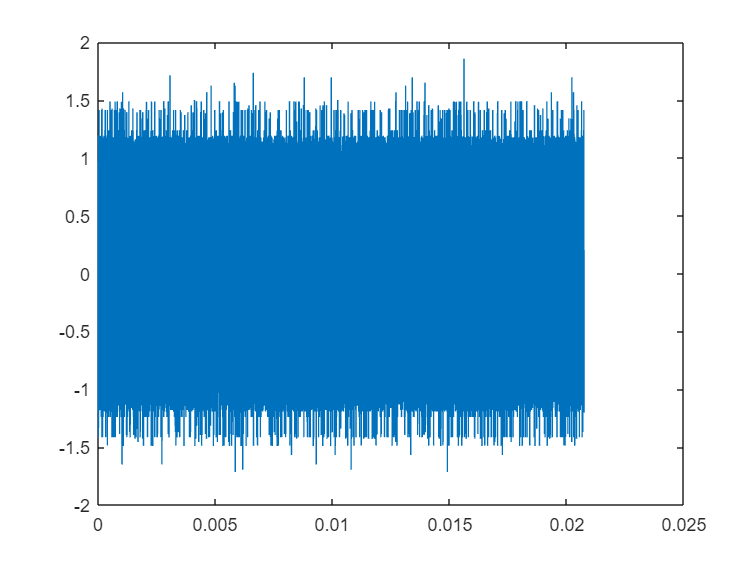


figure;
plot(time_array, data_array)

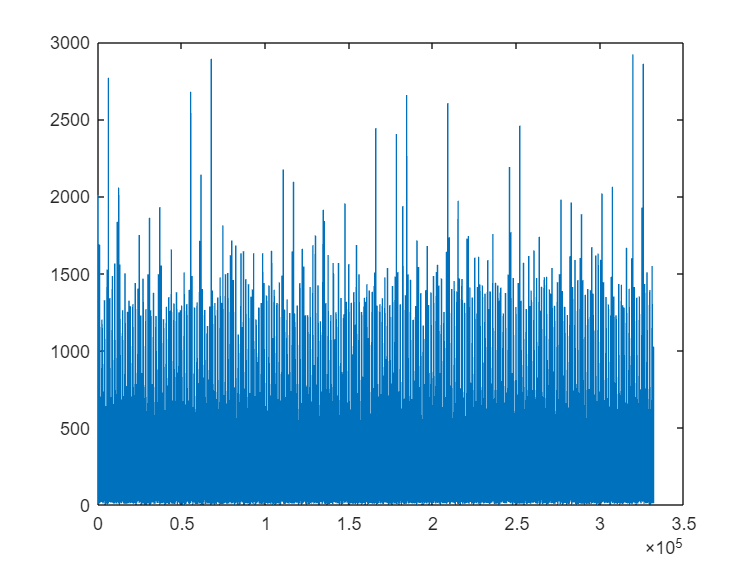

figure;
plot(abs(fft(data_array)))